# Classify Chest X-Ray Images to determine if a Patient has Pneumonia

This example shows how to create a simple network to classify chest Xrays to determine if the patient is healthy or is suffering from pneumonia. You can also expand on this example (depending on the audience) to classify data as CNV, DME, DRUSEN, and NORMAL, the former 3 being different types of Pneumonia. 

## AI Workflow

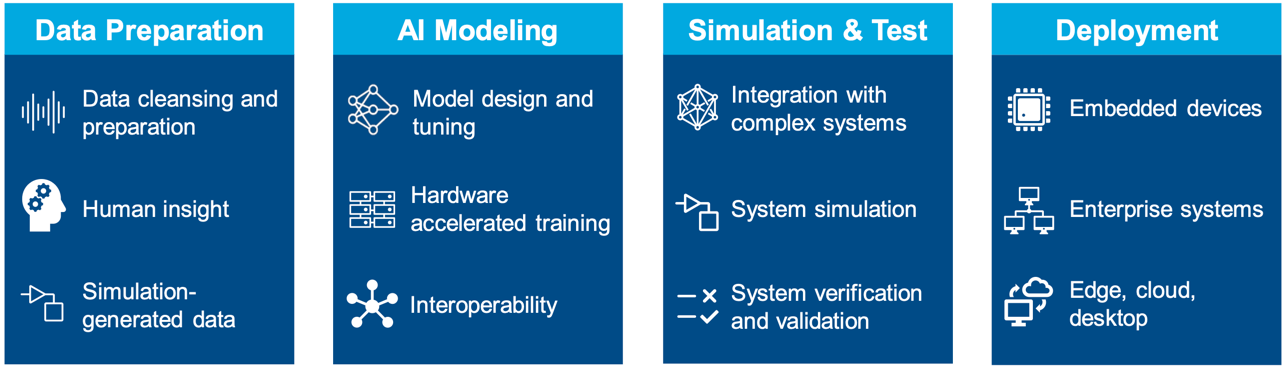

## Add all folders and subfolders to path

addpath('/Users/nsardesa/Library/CloudStorage/OneDrive-MathWorks/Desktop/WebinarContent/Chest_XRay_ForDemo')

## Accessing Data

[Dataset](https://data.mendeley.com/datasets/rscbjbr9sj/2) of validated Optical Coherence Tomography and Chest X-Ray images described and analyzed in "Deep learning-based classification and referral of treatable human diseases" [1]. The OCT Images are split into a training set and a testing set of independent patients. OCT Images are labeled as (disease)-(randomized patient ID)-(image number by this patient) and split into 4 directories: CNV, DME, DRUSEN, and NORMAL.

This dataset is available on [Mendeley](https://www.mendeley.com/) by Elsevier. 

downloadData = false;

if downloadData
    httpsUrl = 'https://data.mendeley.com/public-files/datasets/rscbjbr9sj/files/f12eaf6d-6023-432f-acc9-80c9d7393433/file_downloaded';
    zipData = 'ChestXRay2017.zip';
    DataFileFullPath = websave(zipData, httpsUrl);
end

Unzip downloaded data

unzipFolder = false;

if unzipFolder 
    fileName = "ChestXRay2017.zip";
    unzip(fileName)
end

## Datastores: the Best Way to Handle Data in MATLAB!

A [`datastore`](https://www.mathworks.com/help/releases/R2018b/matlab/ref/datastore.html) is a repository for collections of data that are too large to fit in memory. A `datastore` allows you to read and process data stored in multiple files on a disk, a remote location, or a database as a single entity.  We have preextracted the specific patient slices that correspond to an expert labeled contour of the left ventricle and here we create an [`imageDatastore`](https://www.mathworks.com/help/releases/R2018b/matlab/ref/matlab.io.datastore.imagedatastore.html) to point to all these files.

folderPath = '/Users/nsardesa/Documents/MATLAB/XRay_Example';
trainDataPath = fullfile(folderPath,'chest_xray/train/');
testDataPath = fullfile(folderPath,'chest_xray/test/');

imds_Training = imageDatastore(trainDataPath,'IncludeSubfolders',true, 'LabelSource','foldernames', 'FileExtensions', '.jpeg');
imds_Testing = imageDatastore(testDataPath,'IncludeSubfolders',true, 'LabelSource','foldernames', 'FileExtensions', '.jpeg')

imds_Testing =   ImageDatastore with properties:

                       Files: {
                              ' .../MATLAB/XRay_Example/chest_xray/test/NORMAL/IM-0001-0001.jpeg';
                              ' .../MATLAB/XRay_Example/chest_xray/test/NORMAL/IM-0003-0001.jpeg';
                              ' .../MATLAB/XRay_Example/chest_xray/test/NORMAL/IM-0005-0001.jpeg'
                               ... and 621 more
                              }
                     Folders: {
                              '/Users/nsardesa/Documents/MATLAB/XRay_Example/chest_xray/test'
                              }
                      Labels: [NORMAL; NORMAL; NORMAL ... and 621 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @r

Use the datastore properties to view the dataset at a high level.

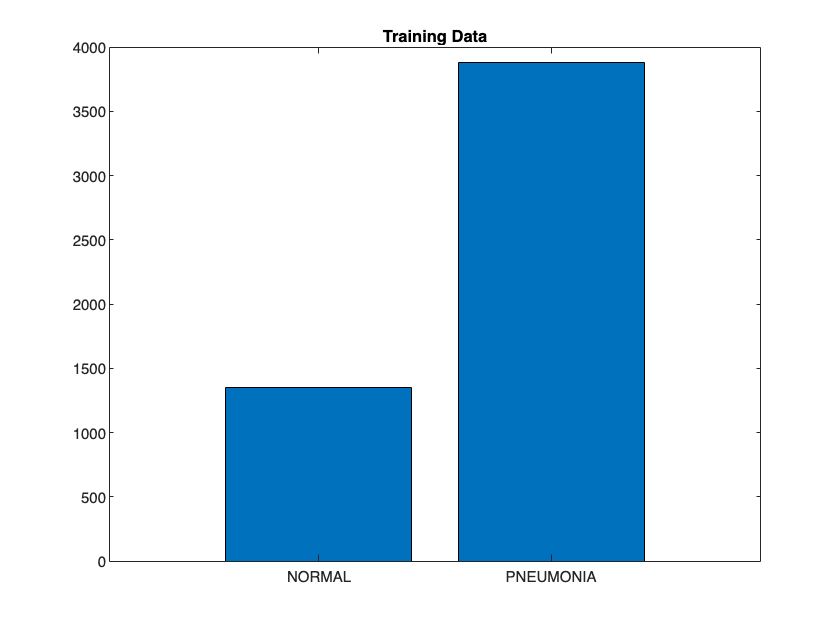

labelCount = countEachLabel(imds_Training);
bar(labelCount.Label,labelCount.Count);
title('Training Data')

## Pre-Process Images

We will be using ResNet-50 to classify our images. There is always scope to compare and contrast our results using different network architectures.

In order for the network to accept our images, they must first be resized (224x224x3). For our network, let's rescale RGB images to grayscale, and resize the image to (300,300)

imds_Training.ReadFcn = @customResizeDatastoreImage;
imds_Testing.ReadFcn = @customResizeDatastoreImage;
imds_Val.ReadFcn = @customResizeDatastoreImage;

### Create a smaller training and validation dataset 

Depending on your laptop capabilities, you can create a smaller dataset to test your network.

[imds_Train_Small,imds_T_2] = splitEachLabel(imds_Training, 250, 'randomized');
[imds_Test_Small,imds_V_2] = splitEachLabel(imds_Testing, 50, 'randomized');
imds_Train_Small = shuffle(imds_Train_Small);
imds_Test_Small = shuffle(imds_Test_Small);

In this section, we decide which dataset we want to work with, the smaller one or the larger one. You generally work with a smaller dataset to setup and test a network quickly.

imds_Train_Now = imds_Training;
imds_Test_Now =  imds_Testing;

## Look at some random images

Let's get a feel for the dataset. Generate a random number less than or equal to total images in the training dataset. Read random image from the datastore and visualize.

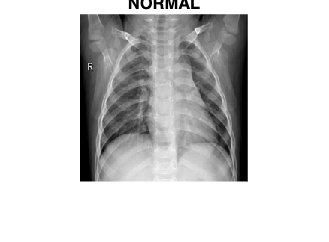

 

randNum = randi(length(imds_Train_Now.Files));

[imTemp,info] = readimage(imds_Train_Now,randNum);
imshow(imTemp)
title(char(info.Label),'Interpreter','none')

imageSize = size(imTemp)

imageSize =    224   224     3


## Create Network Architecture

The [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) (DND) is an app that provides a graphical interface creating and training deep networks. 

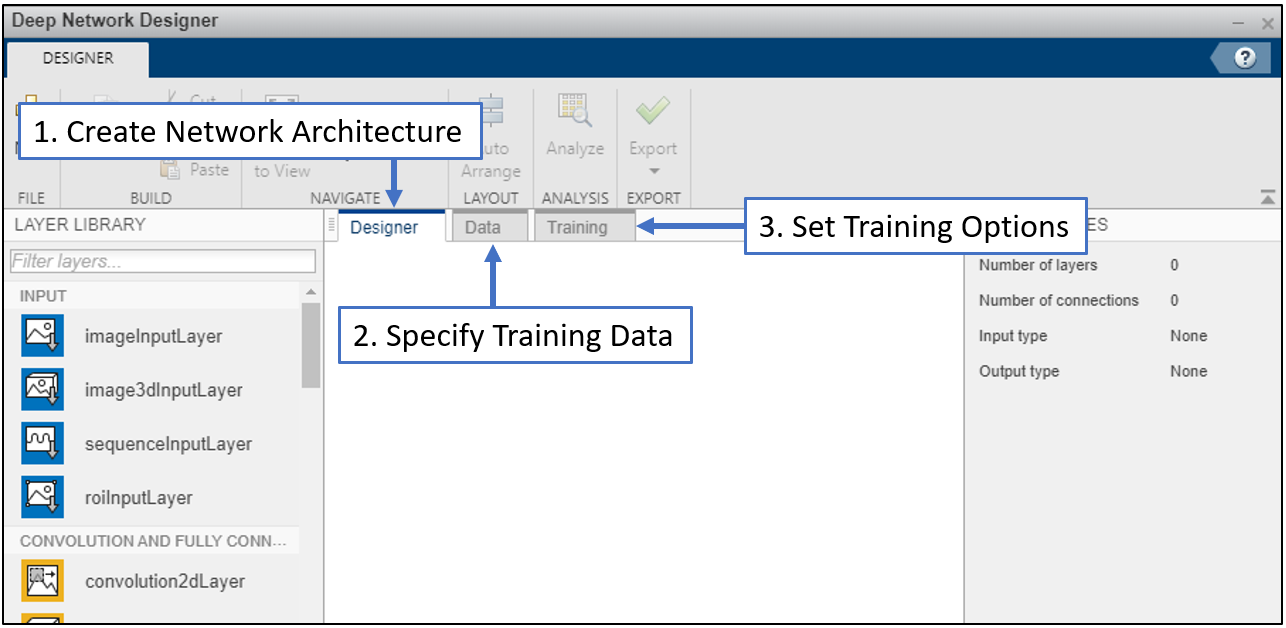

% deepNetworkDesigner 

Select "Blank Network". Create the architecture shown below in the "Designer" tab. Use the parameters shown in the diagram. 

ImageInputSize = 300, 300

Conv Filter size = 

Max Pool = 

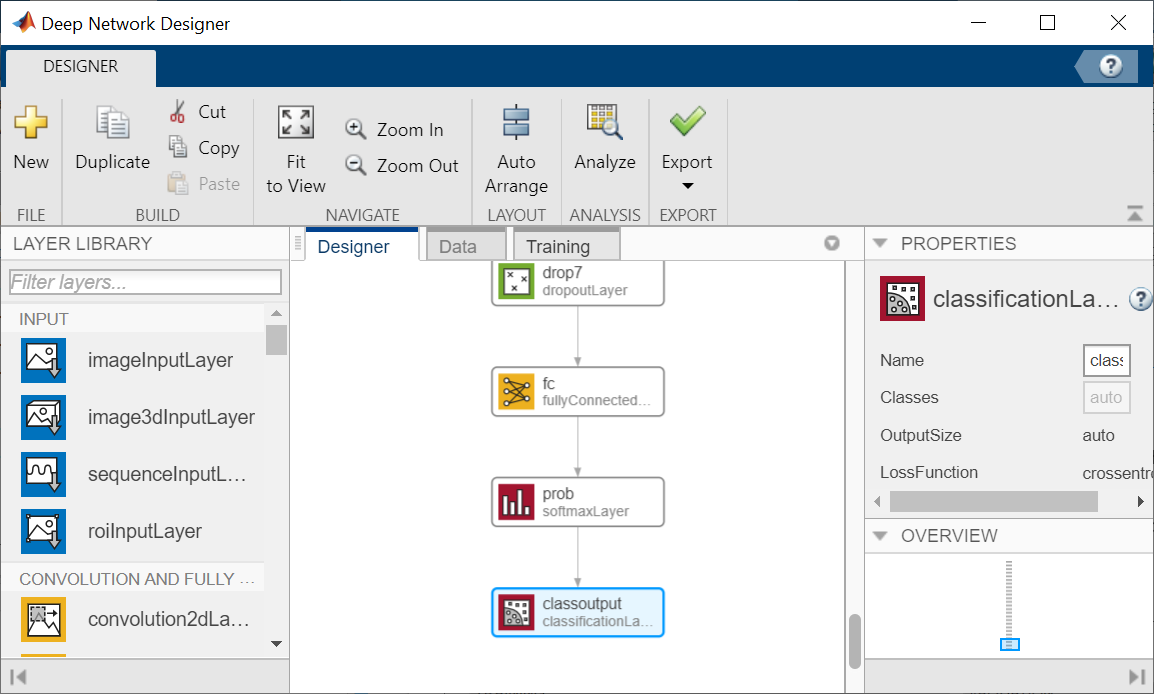

Once you have finished creating the network, export it to the workspace. 

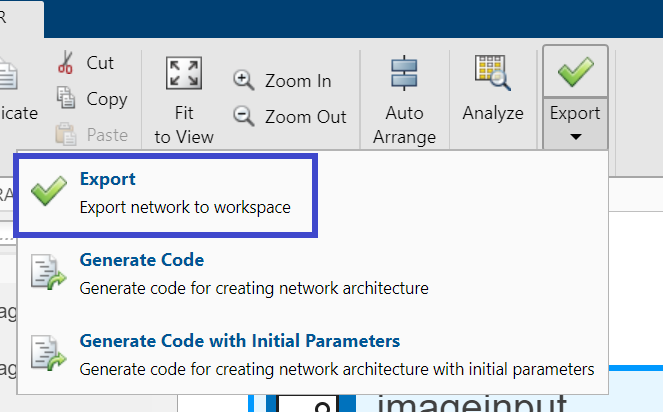

This app not only builds networks from scratch and modifies existing networks, it also allows us to perform the entire training workflow.

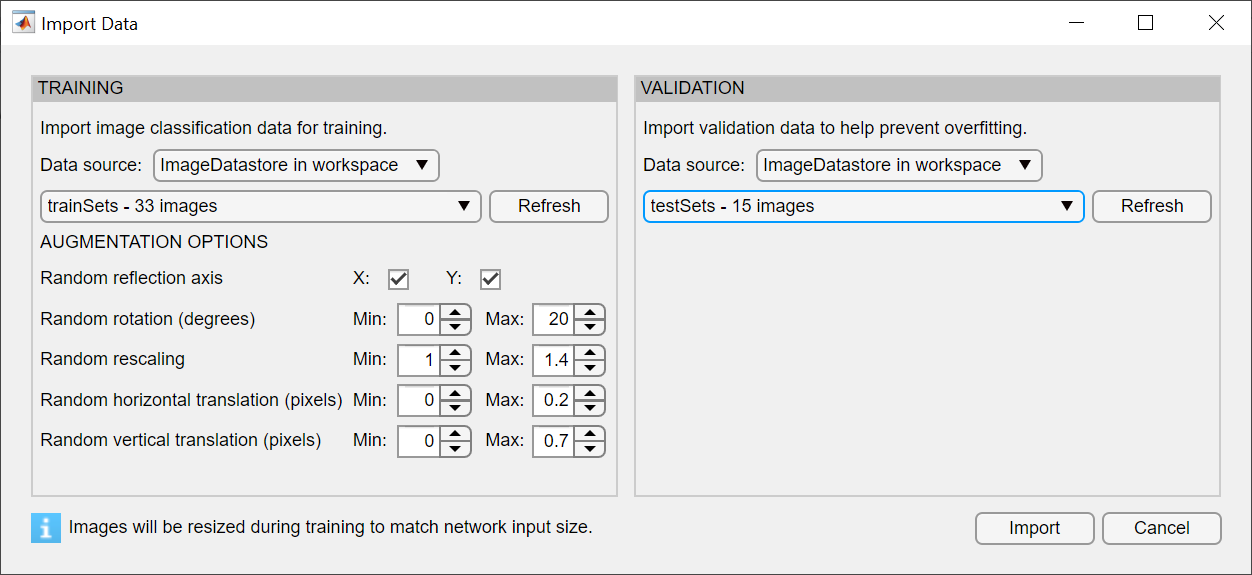

#### Hyperparameter Tuning

Hyperparameters are tunable parameters that are set before training begins. They directly affect how the model trains and how much/what it learns. More information on Training Options are available at: [https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) and in the [Tips and Tricks](https://www.mathworks.com/help/deeplearning/ug/deep-learning-tips-and-tricks.html) page.

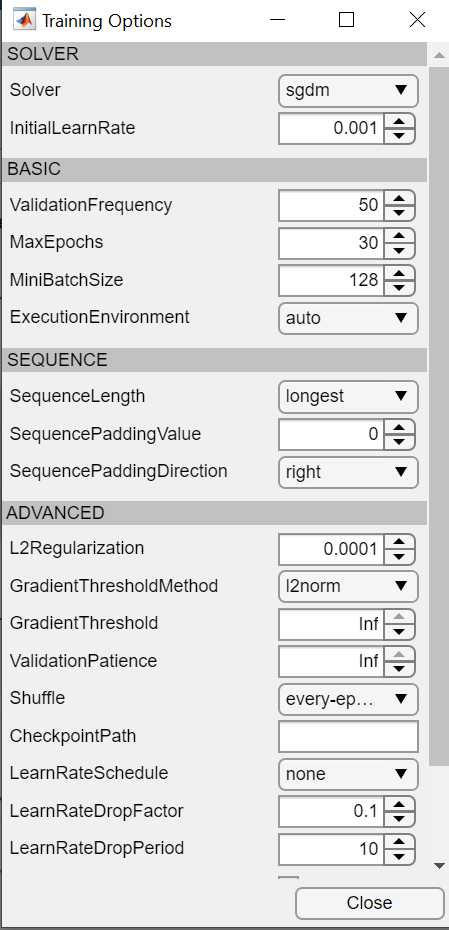

Once training is complete, we can even output the training process to code for future tweaks and improvement.

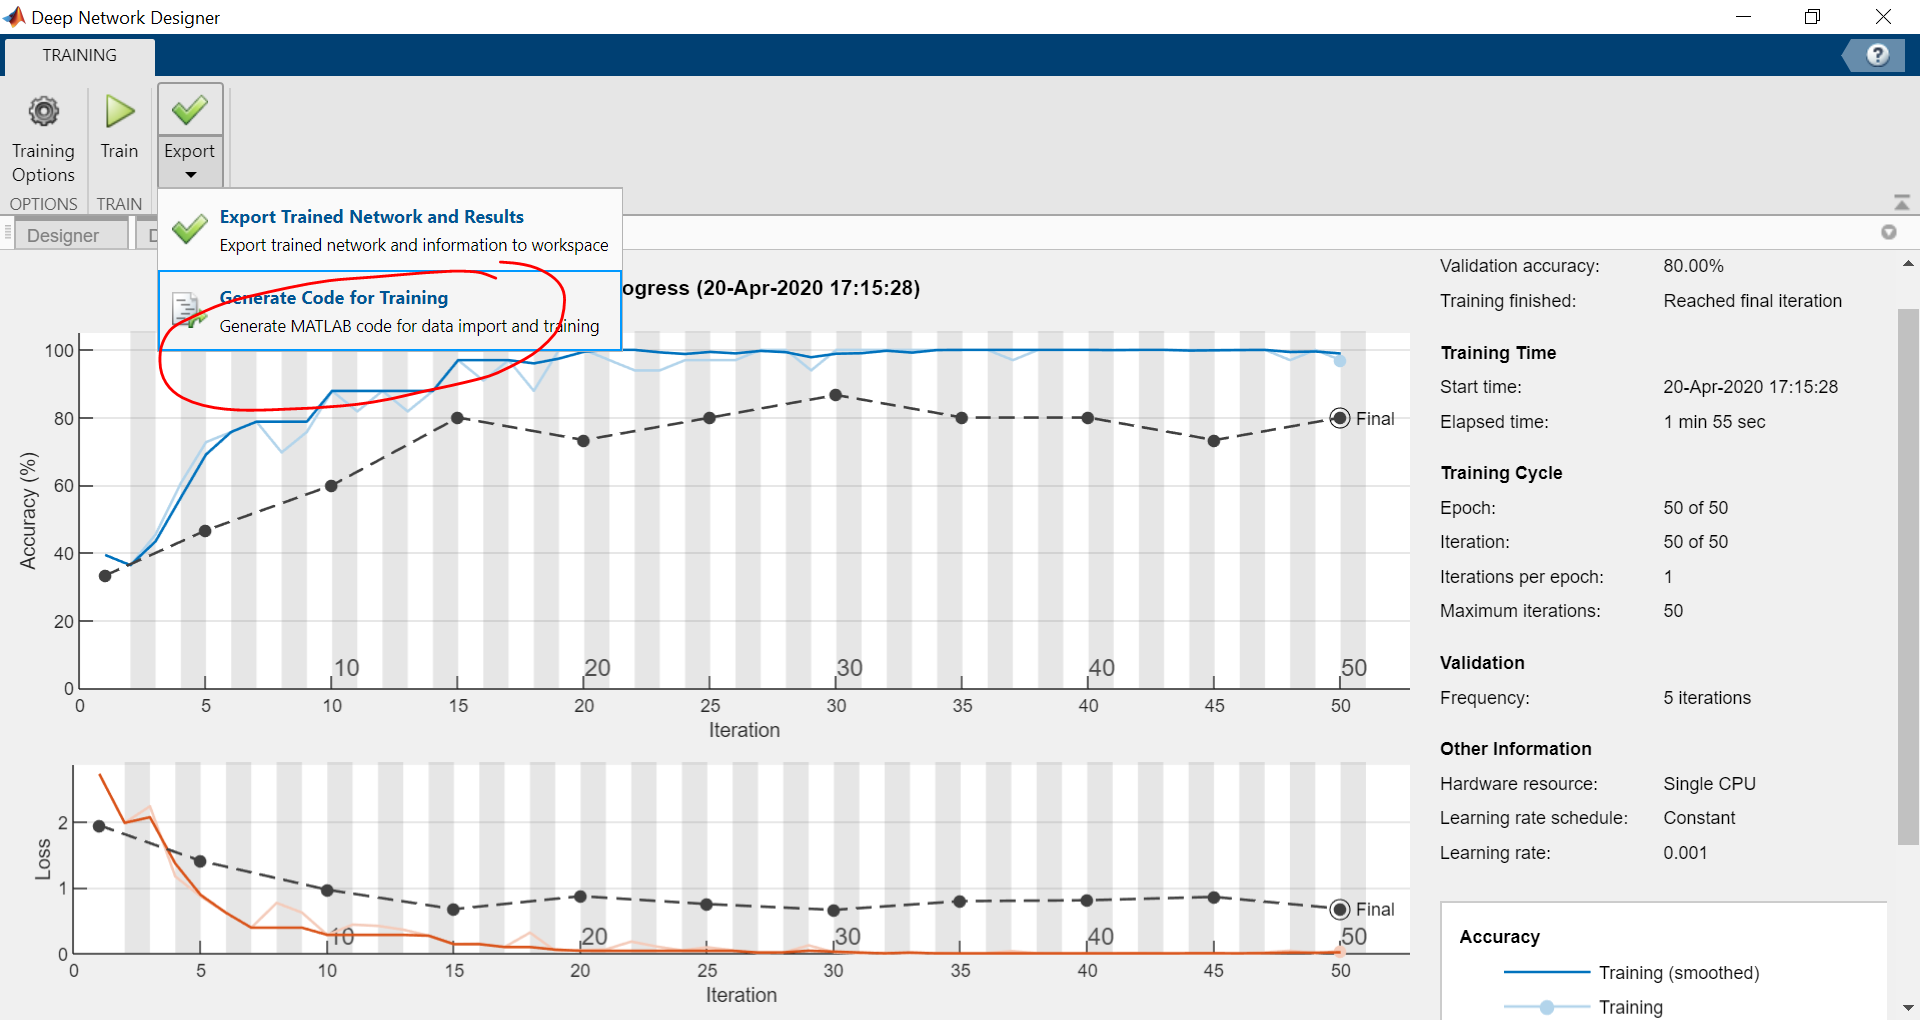

#### Select Architecture without DND 

load("TransferAlexnet.mat")


## Set Training Options and Train

[Training options](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html), AKA hyperparameters, tell our network how to run the training. 

In this section, we will change some of these hyperparameters to see how it affects training:

**Max epochs:** Controls how many times we pass our training images through the network during training.

**Learning Rate: **The network we train tries to minimize a loss function by using an algorithm called gradient descent. The learning rate contributes to whether we can minimize that function. 

-     Too high - the loss function never converges to a minimum. This is what happened when we used the default learning rate.

-     Too low - the loss function converges on a local minima. The accuracy will not be as high as it could be.

% options = trainingOptions("sgdm",...
%     "ExecutionEnvironment","auto",...
%     "InitialLearnRate",0.01,...
%     "Shuffle","every-epoch",...
%     "Plots","training-progress",...
%     "ValidationData",augimdsValidation);
% 
% net = trainNetwork(imds_Train_Now , trainedNetwork_1.Layers, options);


## Evaluate Network Accuracy

Use the [`classify`](https://www.mathworks.com/help/deeplearning/ref/classify.html) command to classify the test dataset

predLabelsTest = classify(trainedNetwork_1, imds_Test_Now);
labelsTest = imds_Test_Now.Labels;
testAccuracy = sum(predLabelsTest == labelsTest) / numel(labelsTest)

testAccuracy = 0.8734

With ResNet - 83 %

AlexNet:

With the smaller dataset, the training accuracy was 74.5%, 83.5%.

With the full dataset, the training accuracy was 79.17%, 80.77%, 87.18%.

81.25% for augmented dataset.

## View Results

randIndx = randi(length(imds_Test_Now.Files));
[imTemp,info] = readimage(imds_Train_Now,randNum);

actualLabel = labelsTest(randIndx);
predictedLabels = classify(trainedNetwork_1,imds_Test_Now);

Display image and prediction

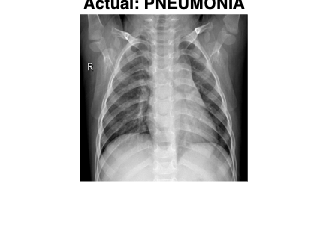

predictedLabel = classify(trainedNetwork_1, imTemp);
imshow(imTemp)
title({['Predicted: ' char(predictedLabel)], ['Actual: ' char(actualLabel)]})

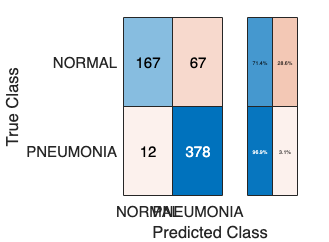

confusionchart(labelsTest, predictedLabels, 'RowSummary','row-normalized')

## Training Resources for Deep Learning in MATLAB

To learn more about how to use deep learning in MATLAB, you can use the following resources:

- [Deep Learning onramp](https://matlabacademy.mathworks.com/details/deep-learning-onramp/deeplearning) - a quick way to get to know the concepts and how to use them in MATLAB

- [Deep Learning with MATLAB](https://matlabacademy.mathworks.com/details/deep-learning-with-matlab/mldl) - a detailed course teaching you deep learning with MATLAB

- [Online Training for AI, Machine Learning, and Deep Learning](https://matlabacademy.mathworks.com/#ai)

## Citations

- Kermany, Daniel; Zhang, Kang; Goldbaum, Michael (2018), “Labeled Optical Coherence Tomography (OCT) and Chest X-Ray Images for Classification”, Mendeley Data, V2, doi: 10.17632/rscbjbr9sj.2

## Functions et. al

function data = customResizeDatastoreImage(filename)
    onState = warning('off', 'backtrace'); 
    c = onCleanup(@() warning(onState)); 
    data = imread(filename); % added lines: 
    data = im2gray(data); 
    data = imresize(data,[224 224]);
    data = cat(3, data, data, data);
end
